clear all;
close all;
clc;

addpath("SensorFusion\");
addpath("funzioni");
run("estraz_dati_sens_fus.m");

Sincronizzazione basata sul tempo degli Encoders (dati puliti).


T_synced = 8826×15 table
    Tempo [s]    X_ARUCO [m]    Y_ARUCO [m]    Z_ARUCO [m]    DegX_ARUCO [deg]    DegY_ARUCO [deg]    DegZ_ARUCO [deg]    OmegaX_IMU [rad/s]    OmegaY_IMU [rad/s]    OmegaZ_IMU [rad/s]    AccX_IMU [g]    AccY_IMU [g]    AccZ_IMU [g]    Left_ENC [tic]    Right_ENC [tic]
    _________    ___________    ___________    ___________    ________________    ________________    ________________    __________________    __________________    __________________    ____________    ____________    ____________

## Encoders Data extraction

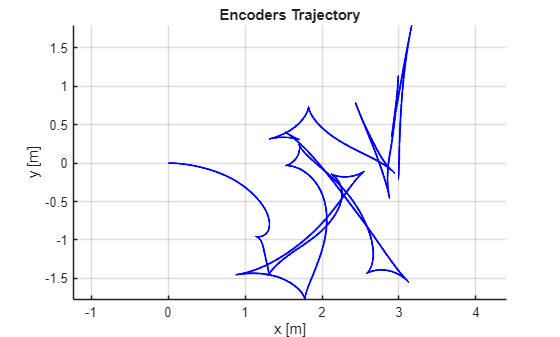

MOTION_START = 1;

b= 0.8291; 
Rr = 0.0873;
Rl = 0.0857;
Enc_res = 4096;

K_param = [b, Rr, Rl];

Ntic_R = table2array(T_synced(1:end,"Right_ENC [tic]"));
Ntic_L = table2array(T_synced(1:end,"Left_ENC [tic]"));

%Tic incremento at each step steps
Ntic_R = diff(Ntic_R);
Ntic_L = diff(Ntic_L);

% pose_Enc_formulas = [x(t) y(t) theta(t)]
pose_Enc_formulas = EncodersMotion(K_param, Ntic_L, Ntic_R, Enc_res);

x_ENC_form = pose_Enc_formulas(1,:);
y_ENC_form = pose_Enc_formulas(2,:);
theta_ENC_form = pose_Enc_formulas(3,:);

figure(4); clf; hold on; grid on;
plot(x_ENC_form, y_ENC_form, 'LineWidth', 1.5, "Color", "b");

xlabel('x [m]');
ylabel('y [m]');
title('Encoders Trajectory');
axis("equal");

## IMU Data extraction

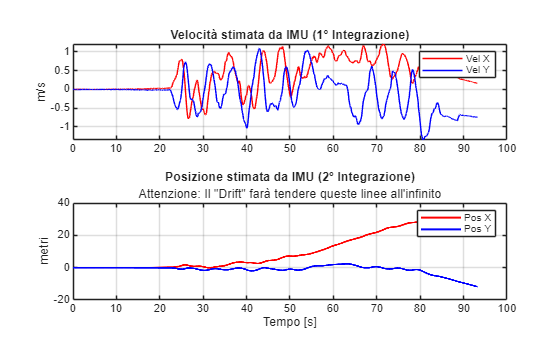

%% --- 1. Preparazione Dati ---
% Estrazione del tempo corrispondente agli indici scelti
% Nota: Deve avere la stessa lunghezza dei dati Acc (MOTION_START:end-1)
Time_IMU = table2array(T_synced(MOTION_START:end-1, "Tempo [s]"));

% Calcolo del passo di campionamento (dt)
% Si assume che sia abbastanza costante
dt = mean(diff(Time_IMU));

% Estrazione Accelerazioni (in g)
AccX_g = table2array(T_synced(MOTION_START:end-1, "AccX_IMU [g]"));
AccY_g = table2array(T_synced(MOTION_START:end-1, "AccY_IMU [g]"));
OmegaZ = table2array(T_synced(MOTION_START:end-1, "OmegaZ_IMU [rad/s]"));
%% --- 2. Conversione e Rimozione Bias (FONDAMENTALE) ---
% Convertiamo da g a m/s^2
g_const = 9.81;
AccX = AccX_g * g_const;
AccY = AccY_g * g_const;

% RIMOZIONE BIAS STATICO
% L'IMU non segna mai 0.000 da fermo. Dobbiamo sottrarre il valore medio iniziale.
% Assumiamo che nei primi 50 campioni il robot fosse fermo.
num_samples_bias = 500; 
bias_X = mean(AccX(1:num_samples_bias));
bias_Y = mean(AccY(1:num_samples_bias));
bias_Omega = mean(OmegaZ(1:num_samples_bias));

% Sottraiamo il bias (Zeroing)
AccX = AccX - bias_X;
AccY = AccY - bias_Y;
OmegaZ = OmegaZ - bias_Omega;

%% --- 3. Integrazione ---
% Pr prima cosa trovo theta
Theta_IMU = cumtrapz(Time_IMU, OmegaZ);
Theta_IMU = - Theta_IMU; % Come scritto sulla consega "Angular velocity on zaxis is opposite"

% Tramite theta trasformo le accelerazioni da frame locale a globale
AccX_Global = -AccX .* cos(Theta_IMU) - AccY .* sin(Theta_IMU);
AccY_Global =  AccX .* sin(Theta_IMU) - AccY .* cos(Theta_IMU); % NB: NON SONO SICURISSIMO SIA GIUSTO!!!!

% 1° Integrazione: Acc -> Vel
VelX_IMU = cumtrapz(Time_IMU, AccX_Global);
VelY_IMU = cumtrapz(Time_IMU, AccY_Global);

% 2° Integrazione: Vel -> Pos
X_IMU = cumtrapz(Time_IMU, VelX_IMU);
Y_IMU = cumtrapz(Time_IMU, VelY_IMU);

%% --- 5. Plot Risultati ---
figure('Name', 'Integrazione IMU', 'Color', 'w');

% Plot Velocità
subplot(2,1,1);
plot(Time_IMU, VelX_IMU, 'r', 'DisplayName', 'Vel X'); hold on;
plot(Time_IMU, VelY_IMU, 'b', 'DisplayName', 'Vel Y');
grid on; legend;
title('Velocità stimata da IMU (1° Integrazione)');
ylabel('m/s');

% Plot Posizione
subplot(2,1,2);
plot(Time_IMU, X_IMU, 'r', 'LineWidth', 1.5, 'DisplayName', 'Pos X'); hold on;
plot(Time_IMU, Y_IMU, 'b', 'LineWidth', 1.5, 'DisplayName', 'Pos Y');
grid on; legend;
title('Posizione stimata da IMU (2° Integrazione)');
subtitle('Attenzione: Il "Drift" farà tendere queste linee all''infinito');
ylabel('metri');
xlabel('Tempo [s]');

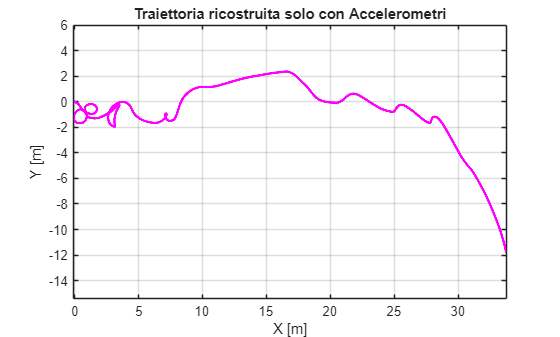


% Plot Traiettoria 2D
figure('Name', 'Traiettoria IMU', 'Color', 'w');
plot(X_IMU, Y_IMU, 'm-', 'LineWidth', 2);
grid on; axis equal;
title('Traiettoria ricostruita solo con Accelerometri');
xlabel('X [m]'); ylabel('Y [m]');

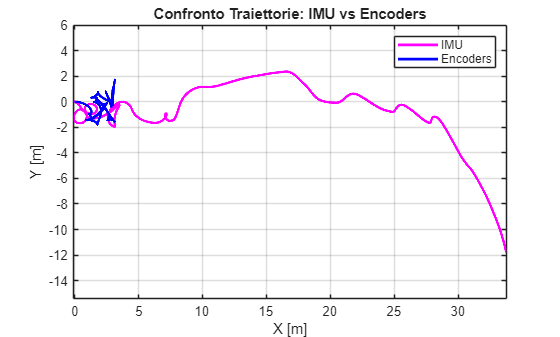

figure('Name', 'Confronto IMU vs ENC', 'Color', 'w');
plot(X_IMU, Y_IMU, 'm-', 'LineWidth', 2, 'DisplayName', 'IMU');
hold on; 
plot(x_ENC_form, y_ENC_form, 'b', 'LineWidth', 2, 'DisplayName', 'Encoders');
grid on; 
axis equal;
legend; 
title('Confronto Traiettorie: IMU vs Encoders');
xlabel('X [m]'); 
ylabel('Y [m]');

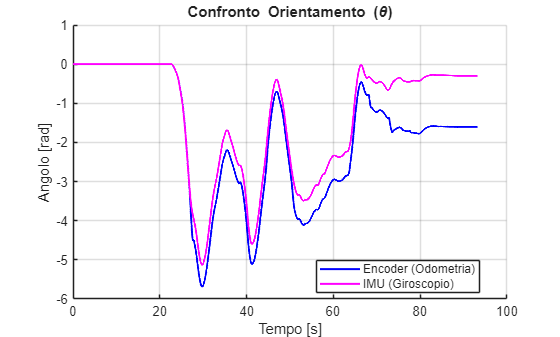

%% --- 1. Confronto Orientamento (Theta) ---
figure(1); clf; hold on; grid on;

plot(Time_IMU, theta_ENC_form, 'b', 'LineWidth', 1.5, 'DisplayName', 'Encoder (Odometria)');
plot(Time_IMU, Theta_IMU, 'm', 'LineWidth', 1.5, 'DisplayName', 'IMU (Giroscopio)');

legend('Location', 'best');
title('Confronto Orientamento (\theta)');
xlabel('Tempo [s]');
ylabel('Angolo [rad]');

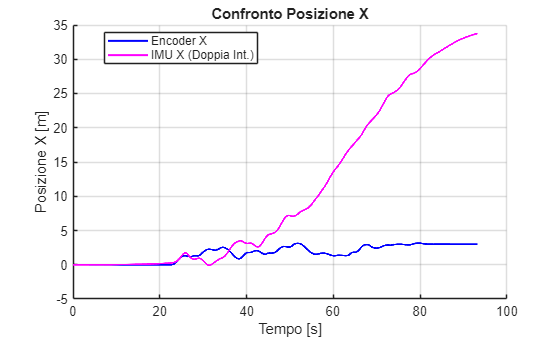

%% --- 2. Confronto Posizione X ---
figure(2); clf; hold on; grid on;

plot(Time_IMU, x_ENC_form, 'b', 'LineWidth', 1.5, 'DisplayName', 'Encoder X');
plot(Time_IMU, X_IMU, 'm', 'LineWidth', 1.5, 'DisplayName', 'IMU X (Doppia Int.)');

legend('Location', 'best');
title('Confronto Posizione X');
xlabel('Tempo [s]');
ylabel('Posizione X [m]');

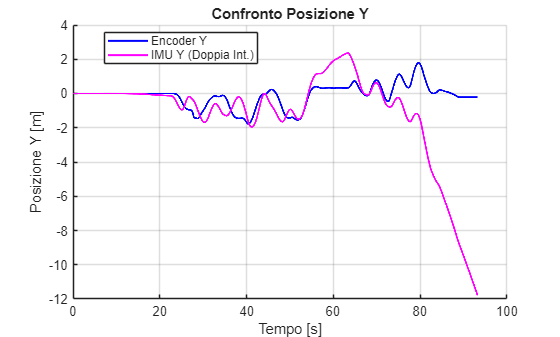

%% --- 3. Confronto Posizione Y ---
figure(3); clf; hold on; grid on;

plot(Time_IMU, y_ENC_form, 'b', 'LineWidth', 1.5, 'DisplayName', 'Encoder Y');
plot(Time_IMU, Y_IMU, 'm', 'LineWidth', 1.5, 'DisplayName', 'IMU Y (Doppia Int.)');

legend('Location', 'best');
title('Confronto Posizione Y');
xlabel('Tempo [s]');
ylabel('Posizione Y [m]');

## Real Sense Data

Now we also analize the RS data

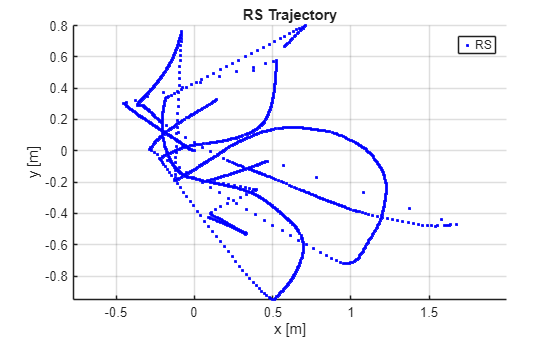

% RS data extraction
x_RS = table2array(T_synced(1:end-1, "X_ARUCO [m]"));
x_RS(1) = 0; % was NaN
y_RS = table2array(T_synced(1:end-1, "Y_ARUCO [m]"));
y_RS(1) = 0; % was NaN
theta_RS = table2array(T_synced(1:end-1, "DegZ_ARUCO [deg]")); %deg around Z
theta_RS = unwrap(theta_RS); %to solve phase problems
theta_RS = deg2rad(theta_RS); %rad
theta_RS(1) = 0; % was NaN

figure(2); clf; hold on; grid on;
plot(x_RS, y_RS, '.', 'LineWidth', 1.5, "Color", "b");
xlabel('x [m]');
ylabel('y [m]');
title('RS Trajectory');
legend('RS');
axis("equal");

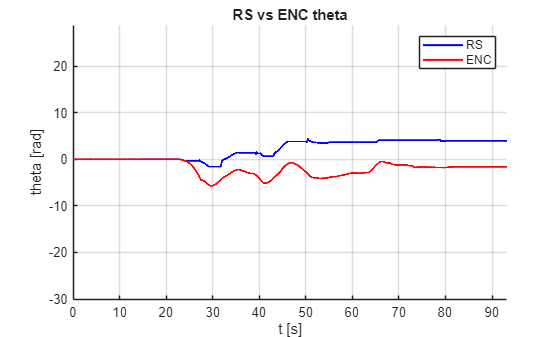

t = table2array(T_synced(1:end-1, "Tempo [s]"));

figure(3); clf; hold on; grid on;
plot(t, theta_RS, 'LineWidth', 1.5, "Color", "b"); 
plot(t, theta_ENC_form, 'LineWidth', 1.5, "Color", "r");
xlabel('t [s]');
ylabel('theta [rad]');
title('RS vs ENC theta');
legend('RS', 'ENC')
axis("equal");

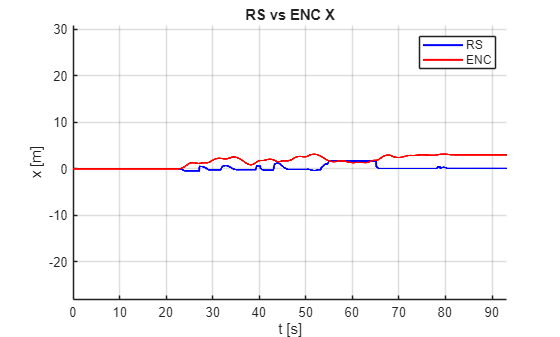

figure(4); clf; hold on; grid on;
plot(t, x_RS, 'LineWidth', 1.5, "Color", "b");
plot(t, x_ENC_form, 'LineWidth', 1.5, "Color", "r");
xlabel('t [s]');
ylabel('x [m]');
title('RS vs ENC X');
legend('RS', 'ENC')
axis("equal");

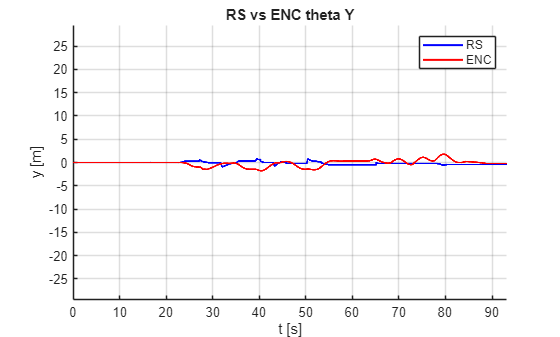

figure(5); clf; hold on; grid on;
plot(t, y_RS, 'LineWidth', 1.5, "Color", "b");
plot(t, y_ENC_form, 'LineWidth', 1.5, "Color", "r");
xlabel('t [s]');
ylabel('y [m]');
title('RS vs ENC theta Y');
legend('RS', 'ENC');
axis("equal");

## State transition model

**NOTE: **for all the nomenclature see paper [https://ieeexplore.ieee.org/document/10777435](https://ieeexplore.ieee.org/document/10777435))

Here are reported:

-  the odometry equations (from  Antonelli and Chiaverini) 

- The matrix F of the EKF 

- The covariance matrix of the process (odometry) Q

The last 2 are computed in using the function print_syst().

Q = print_syst();

$$x\_new = x+\frac{\pi \,\cos\left(\theta -\frac{\pi \,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}-{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}\,b}\right)\,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}+{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}$$

$$y\_new = y+\frac{\pi \,\sin\left(\theta -\frac{\pi \,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}-{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}\,b}\right)\,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}+{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}$$

$$theta\_new = \theta -\frac{2\,\pi \,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}-{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}\,b}$$

$$J\_symbolic = \left(\begin{array}{ccc} 1 & 0 & -\frac{\pi \,\sin\left(\theta -\frac{\pi \,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}-{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}\,b}\right)\,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}+{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}\\ 0 & 1 & \frac{\pi \,\cos\left(\theta -\frac{\pi \,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}-{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}\,b}\right)\,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}+{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}\\ 0 & 0 & 1 \end{array}\right)$$

Q

## Measurement Model RS

Here the covariance matrix of the data from the RS is derived.

sigma_x_RS = var(x_RS(1:MOTION_START));
sigma_y_RS= var(y_RS(1:MOTION_START));
sigma_theta_RS = var(theta_RS(1:MOTION_START));

variances_vector_RS = [sigma_x_RS, sigma_y_RS, sigma_theta_RS];

R_RS = diag(variances_vector_RS) 

## EKF Using only RS 

Now we implement the EKF with only RS data.

n = length(Ntic_R);
b= 0.8291; 
Rr = 0.0873;
Rl = 0.0857;
Enc_res = 4096;

theta_incr = zeros(1, n);

X_prior = zeros(3, n); % [x, y, theta]
X_post = zeros(3, n);

Z_HTC = [x_HTC' ; y_HTC' ; theta_HTC'];
Z_RS = [x_RS' ; y_RS' ; theta_RS'];

P = R_HTC; %Initialization of P

%TRY TO BALANCE COV MATRICES (BACAUSE RS DATA SUCKS)
Q_try = Q
R_RS = diag(variances_vector_RS)*10^10 
for i = 1:n-1
    
    % Prediction
    theta_incr(i+1) = 2*pi * (Ntic_R(i)*Rr-Ntic_L(i)*Rl) / (Enc_res*b);
    
    X_prior(1, i+1) = X_post(1, i) + pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * cos(X_post(3, i) + theta_incr(i)/2);
    X_prior(2, i+1) = X_post(2, i) + pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * sin(X_post(3, i) + theta_incr(i)/2);
    X_prior(3, i+1) = X_post(3, i) + theta_incr(i);
    
    F = [ 1    0    -pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * sin(X_post(3, i) + theta_incr(i)/2);            
          0    1     pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * cos(X_post(3, i) + theta_incr(i)/2); 
          0    0                               1                                                  ];

    P = F*P*F' + Q;


    % Update: RS
    if (Z_RS(:, i+1) - Z_RS(:, i) ~= 0)
        K2 = (P * H') / (H * P * H' + R_RS);
        X_post(:,i+1) = X_prior(:,i+1) + K2*(Z_RS(:,i+1) - X_prior(:,i+1));
        P = (eye(3) - K2 * H) * P;
    else
        X_post(:,i+1) = X_prior(:,i+1);
    end

end 

figure(7); clf; hold on; grid on;
plot(X_post(1,:), X_post(2,:), 'LineWidth', 1.5, "Color", "r");
plot(x_RS, y_RS, 'LineWidth', 1.5, "Color", "g", "LineStyle","--");
xlabel('x [m]');
ylabel('y [m]');
title('Calibrated Data');
legend('KAL RS', 'RS');
axis("equal");
